# Single Damped Pendulum

Use the interactive controls below to explore the motion of a damped pendulum.

    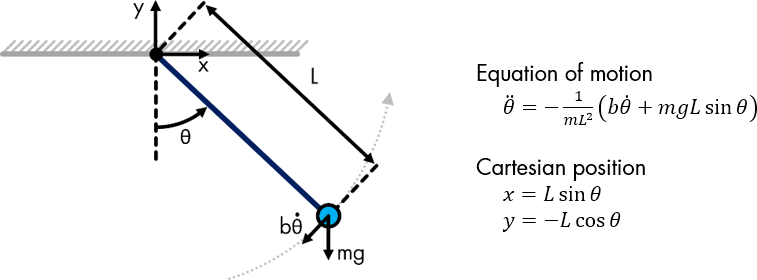

% Define physical parameters
L = 1; % Pendulum length (m)
m = 1; % Pendulum mass (kg)
theta0 = 90; % Initial angle (deg)
b = 1; % Damping (N*m*s/rad)
g = 9.81; % Gravity (m/s^2)
plotResults = true; % Flag to plot results
 

% Convert initial angle to radians
theta0 = deg2rad(theta0);

% Numerically solve the pendulum's equation of motion
[t,theta] = pendulumSolver(L,m,b,g,theta0);

% Get the number of elements
N = length(theta);

% Convert to Cartesian coordinates
x = L*sin(theta);
y = -L*cos(theta);

% Count the number of peaks using the Find Local Extrema Live Editor task

% Find local maxima
maxIndices = islocalmax(x,"MinProminence",0.001);
numPeaks = sum(maxIndices);

% Display results
disp("Initial (x,y):  (" + x(1) + "," + y(1) + ")")
disp("Final (x,y):    (" + x(end) + "," + y(end) + ")")
disp("Oscillations:   " + numPeaks)

% Plot x-position versus time
if plotResults
    plot(t,x,"b-")
    hold on
    plot(t,y,"r--")
    plot(t(maxIndices),x(maxIndices),"mo")
    hold off
    xlabel("Time (s)")
    ylabel("Position (m)")
    title("Pendulum Motion")
    if numPeaks>0
        legend("x","y","Oscillation")
    else
        legend("x","y")
    end
    grid on
    ylim(1.1*[-L,L])
end

*Copyright 2021 The MathWorks, Inc.*